close all
clc
clear

# Задание 1

## Эксперимент 1

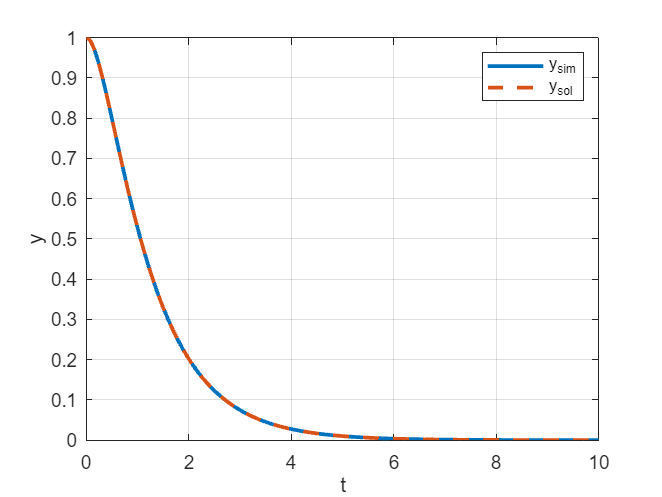

%% Время
t_start = 0;
t_end = 10;

%% Коэффициенты

lambda_1 = -3;
lambda_2 = -1;
a0 = 3;
a1 = 4;
c1 = -1/2;
c2 = 3/2;

%% Начальные условия
y0 = 1;
dy0 = 0;

%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on

y_real = c1 .* exp(lambda_1 * t) + c2 .* exp(lambda_2 * t);
plot(t, y_real, 'LineWidth', 2, 'LineStyle','--');
legend('y_{sim}', 'y_{sol}');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '1_1.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\1_1.png


## Эксперимент 2

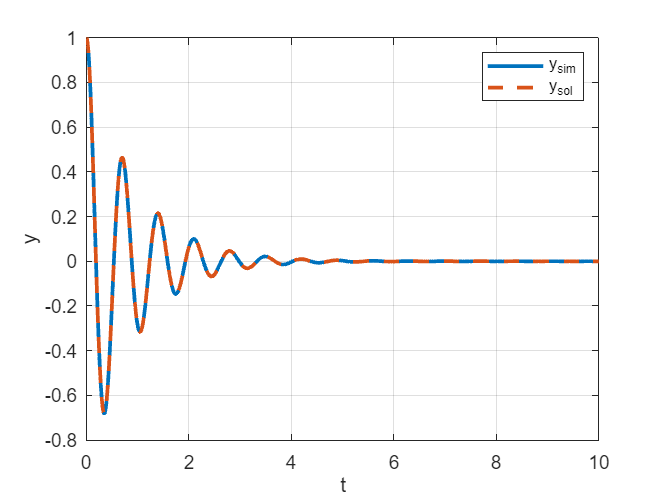

%% Время
t_start = 0;
t_end = 10;

%% Коэффициенты

a0 = 82.21;
a1 = 2.2;
c1 = 1.1/9;
c2 = 1;

%% Начальные условия
y0 = 1;
dy0 = 0;

%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on

y_real = c2 .* exp(-1.1 * t) .* cos(9*t) + c1 .* exp(-1.1 * t) .* sin(9*t);
plot(t, y_real, 'LineWidth', 2, 'LineStyle','--');
legend('y_{sim}', 'y_{sol}');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '1_2.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\1_2.png


## Эксперимент 3

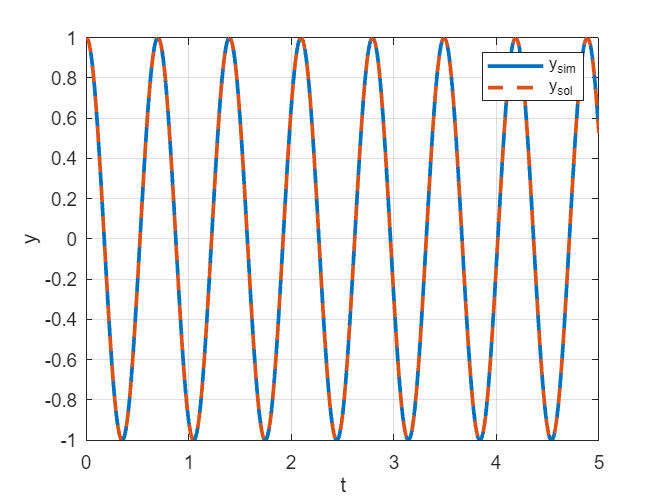

save_filename = '1_3.png'; % Имя файла

%% Время
t_start = 0;
t_end = 5;

%% Коэффициенты

a0 = 81;
a1 = 0;
c1 = 0;
c2 = 1;

%% Начальные условия
y0 = 1;
dy0 = 0;

%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on

y_real = c2 .* cos(9*t);
plot(t, y_real, 'LineWidth', 2, 'LineStyle','--');
legend('y_{sim}', 'y_{sol}');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\1_3.png


## Эксперимент 4

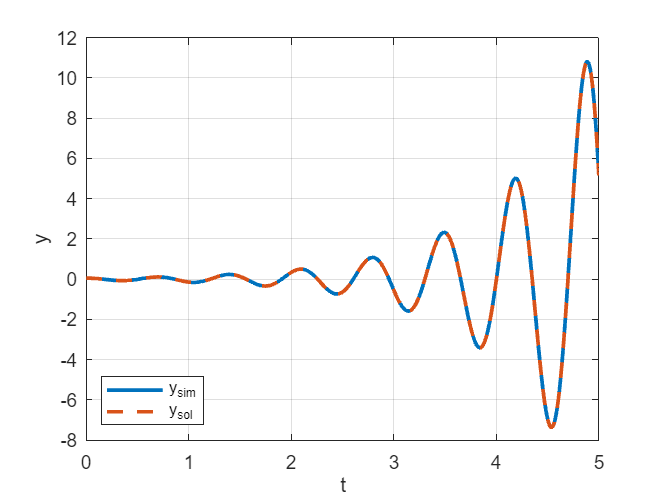

%% Время
t_start = 0;
t_end = 5;

%% Коэффициенты

a0 = 82.21;
a1 = -2.2;
c1 = -0.055/9;
c2 = 0.05;

%% Начальные условия
y0 = 0.05;
dy0 = 0;

%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on;

y_real = exp(1.1 * t) .* (c2 * cos(9 * t) + c1 * sin(9 * t));
plot(t, y_real, 'LineWidth', 2, 'LineStyle','--');
legend('y_{sim}', 'y_{sol}', 'Location', 'southwest');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '1_4.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\1_4.png


## Эксперимент 5

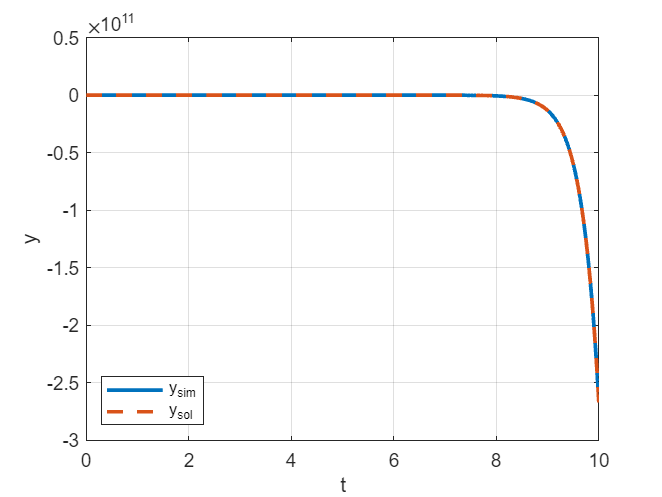

%% Время
t_start = 0;
t_end = 10;

%% Коэффициенты

lambda_1 = 3;
lambda_2 = 1;
a0 = 3;
a1 = -4;
c1 = -1/40;
c2 = 3/40;

%% Начальные условия
y0 = 0.05;
dy0 = 0;

%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on;

y_real = c1 .* exp(lambda_1 * t) + c2 .* exp(lambda_2 * t);
plot(t, y_real, 'LineWidth', 2, 'LineStyle','--');
legend('y_{sim}', 'y_{sol}', 'Location', 'southwest');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '1_5.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\1_5.png


## Эксперимент 6

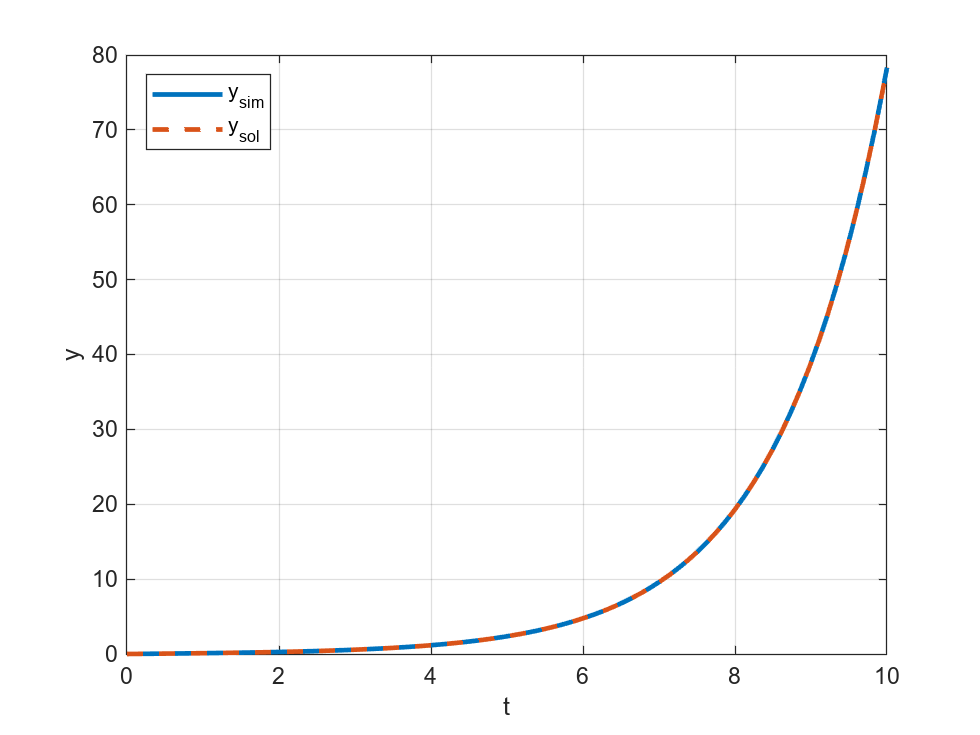

%% Время
t_start = 0;
t_end = 10;

%% Коэффициенты

lambda_1 = -0.7;
lambda_2 = 0.7;
a0 = -0.49;
a1 = 0;
c1 = -1/14;
c2 = 1/14;

%% Начальные условия
y0 = 0;
dy0 = 0.1;

%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on;

y_real = c1 .* exp(lambda_1 * t) + c2 .* exp(lambda_2 * t);
plot(t, y_real, 'LineWidth', 2, 'LineStyle','--');
legend('y_{sim}', 'y_{sol}', 'Location', 'northwest');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '1_6.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\1_6.png



close all
clc
clear

close all
clc
clear

# Задание 2

## Область устойчивости при T2 const

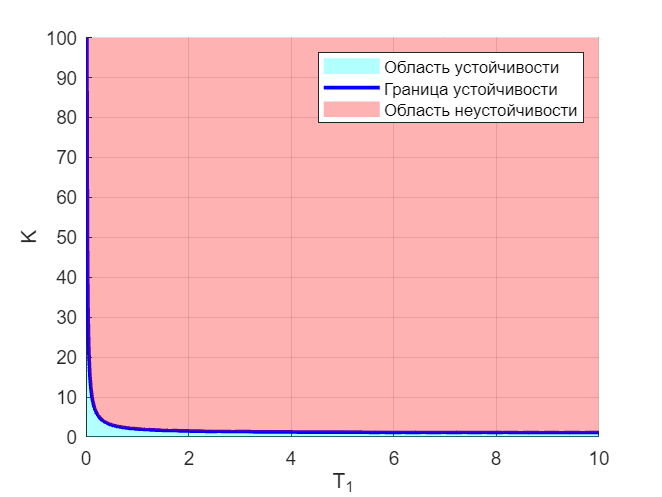

% Определяем диапазон для T1
T1 = linspace(0.01, 10, 1000); % T1 > 0, исключая 0 для избежания деления на 0

% Рассчитываем границу для K
K_boundary = (1 + T1) ./ T1;

% Построение графика
fig = figure;
hold on;
fill([T1, fliplr(T1)], [zeros(size(K_boundary)), fliplr(K_boundary)], 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(T1, K_boundary, 'b', 'LineWidth', 2);

% Закрашиваем область неустойчивости (светло-красный)
fill([T1, fliplr(T1)], [K_boundary, fliplr(ones(size(K_boundary)) * max(K_boundary) * 1.2)], 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Оформление графика
xlabel('T_1');
ylabel('K');
ylim([0 100])
grid on;
legend('Область устойчивости', 'Граница устойчивости', 'Область неустойчивости',  'Location', 'NorthEast');
hold off;

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '2_1.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600);

## Область устойчивости при T1 const

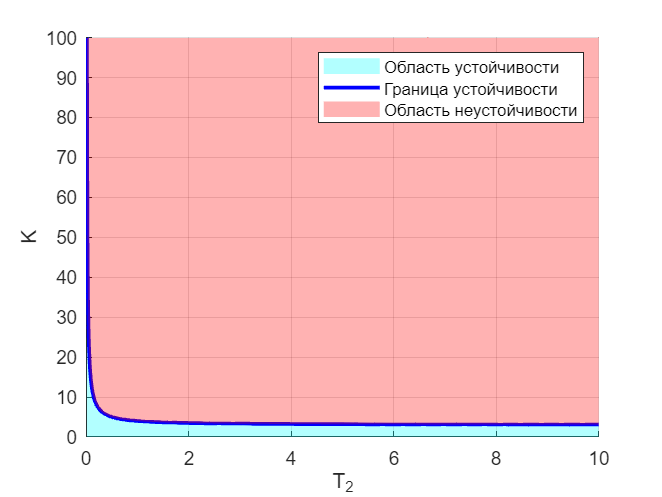

% Определяем диапазон для T1
T2 = linspace(0.01, 10, 1000); % T1 > 0, исключая 0 для избежания деления на 0

% Рассчитываем границу для K
K_boundary = (1 +3* T2) ./ T2;

% Построение графика
fig = figure;
hold on;
fill([T2, fliplr(T2)], [zeros(size(K_boundary)), fliplr(K_boundary)], 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(T2, K_boundary, 'b', 'LineWidth', 2);

% Закрашиваем область неустойчивости (светло-красный)
fill([T2, fliplr(T2)], [K_boundary, fliplr(ones(size(K_boundary)) * max(K_boundary) * 1.2)], 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Оформление графика
xlabel('T_2');
ylabel('K');
ylim([0 100])
grid on;
legend('Область устойчивости', 'Граница устойчивости', 'Область неустойчивости',  'Location', 'NorthEast');
hold off;

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '2_2.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600);

## Эксперимент 1

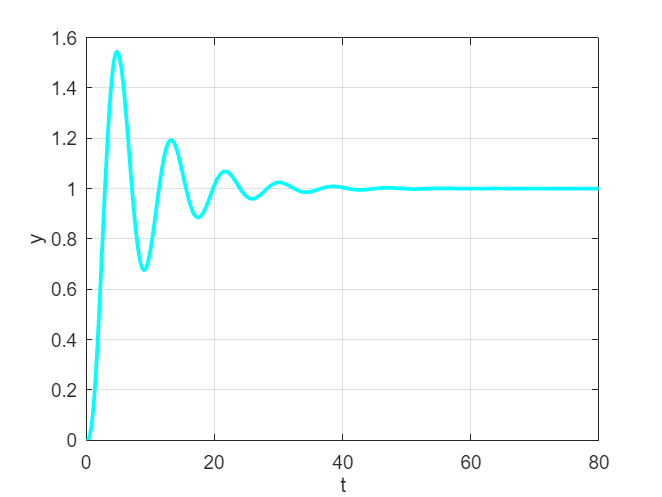

%% Время
t_start = 0;
t_end = 80;

%% Коэффициенты

T1 = 1;
T2 = 1;
K = 1;

%% Моделирование
% Укажите путь к модели
model_name = 'sim2';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2, color='cyan');
xlabel('t');
ylabel('y');
title('');
grid on;
hold on

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '2_3.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\2_3.png


## Эксперимент 2

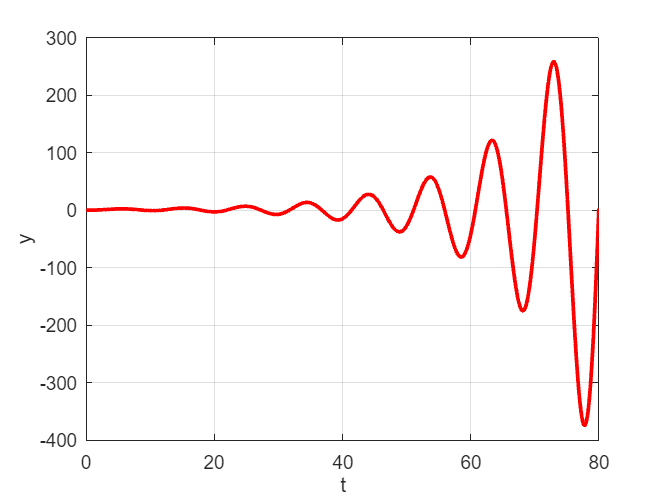

%% Время
t_start = 0;
t_end = 80;

%% Коэффициенты

T1 = 2;
T2 = 2;
K = 2;

%% Моделирование
% Укажите путь к модели
model_name = 'sim2';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2, color='red');
xlabel('t');
ylabel('y');
title('');
grid on;
hold on

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '2_4.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\2_4.png


## Эксперимент 3

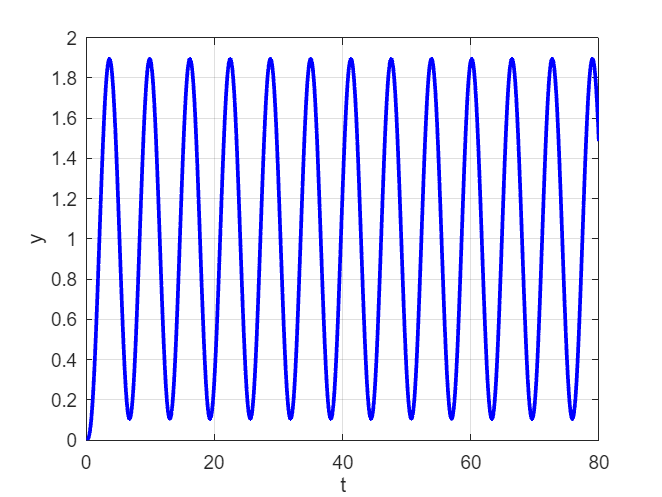

%% Время
t_start = 0;
t_end = 80;

%% Коэффициенты

T1 = 1;
T2 = 1;
K = 2;

%% Моделирование
% Укажите путь к модели
model_name = 'sim2';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y.Time;
signal = sim_out.y.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2, color='b');
xlabel('t');
ylabel('y');
title('');
grid on;
hold on

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '2_5.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\2_5.png


# Задание 3

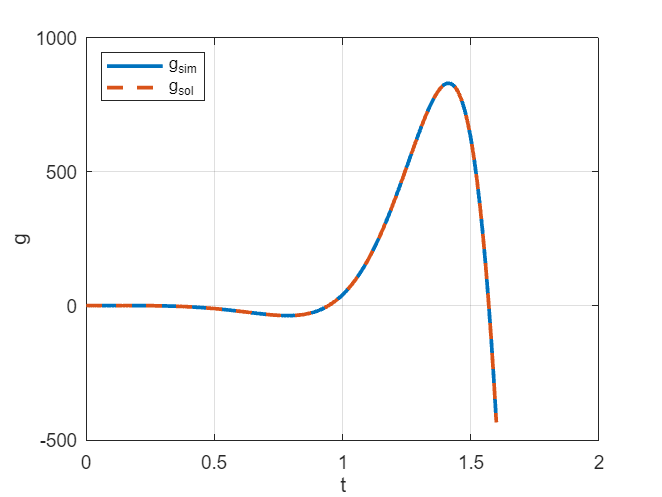

% Время
t_start = 0;
t_end =1.6;
%% Моделирование
% Укажите путь к модели
model_name = 'sim3';  % Имя модели без расширения

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));             % Время окончания симуляции

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.g.Time;
signal = sim_out.g.Data;

% Построение графика
fig = figure;
plot(t, signal, 'LineWidth', 2);
xlabel('t');
ylabel('g');
title('');
grid on;
hold on;

y_real = sin (-5*t) + exp(5*t) .* cos(-5 *t);
plot(t, signal, 'LineWidth', 2, 'LineStyle','--');
legend('g_{sim}', 'g_{sol}', 'Location', 'northwest');

% Установка пути и имени файла для сохранения
save_path = 'C:\Users\vasil\Desktop\lsau\lab2\report\images'; % Замените на свой путь
save_filename = '3_1.png'; % Имя файла

% Полный путь к файлу
full_save_path = fullfile(save_path, save_filename);

% Сохранение графика
exportgraphics(fig, full_save_path, "Resolution",600); 

disp(['График сохранен по пути: ' full_save_path]);

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab2\report\images\3_1.png


syms x1 x2 x3 x4 c1 c2 c3 c4 t
C = [c1 c2 c3 c4];
A = sym([0 5 0 0;
    -5 0 0 0;
    0 0 5 5;
    0 0 -5 5]);
x = [x1; x2; x3; x4];
A = funm(A, 'exp');
g = C*A*x

$$g = \begin{array}{l} x_{1}\,\left(c_{1}\,\left(\frac{{\mathrm{e}}^{-5\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{5\,\mathrm{i}}}{2}\right)-c_{2}\,\sigma_{2}\right)+x_{2}\,\left(c_{2}\,\left(\frac{{\mathrm{e}}^{-5\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{5\,\mathrm{i}}}{2}\right)+c_{1}\,\sigma_{2}\right)+x_{3}\,\left(c_{3}\,\sigma_{3}-c_{4}\,\sigma_{1}\right)+x_{4}\,\left(c_{4}\,\sigma_{3}+c_{3}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{5-5\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{5+5\,\mathrm{i}}\,\mathrm{i}}{2}\\ \sigma_{2}=\frac{{\mathrm{e}}^{-5\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{5\,\mathrm{i}}\,\mathrm{i}}{2}\\ \sigma_{3}=\frac{{\mathrm{e}}^{5-5\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{5+5\,\mathrm{i}}}{2} \end{array}$$

simplify(g)

$$ans = \begin{array}{l} x_{1}\,\left(c_{1}\,\left(\frac{{\mathrm{e}}^{-5\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{5\,\mathrm{i}}}{2}\right)-c_{2}\,\sigma_{2}\right)+x_{2}\,\left(c_{2}\,\left(\frac{{\mathrm{e}}^{-5\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{5\,\mathrm{i}}}{2}\right)+c_{1}\,\sigma_{2}\right)+x_{3}\,\left(c_{3}\,\sigma_{3}-c_{4}\,\sigma_{1}\right)+x_{4}\,\left(c_{4}\,\sigma_{3}+c_{3}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{5-5\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{5+5\,\mathrm{i}}\,\mathrm{i}}{2}\\ \sigma_{2}=\frac{{\mathrm{e}}^{-5\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{5\,\mathrm{i}}\,\mathrm{i}}{2}\\ \sigma_{3}=\frac{{\mathrm{e}}^{5-5\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{5+5\,\mathrm{i}}}{2} \end{array}$$